plot: 

- poles/zeros diagram

- filter transfer function

- mention filter coafficients in plots?


% Define the low and high cutoff frequencies for the bandpass filter (in Hz)
lowCutoff = low_cutoff/fn; % Lower cutoff frequency
highCutoff = high_cutoff/fn % Upper cutoff frequency

highCutoff = 0.4000


if method=='butterworth'
    if type== 'lp'
        [b, a] = butter(order, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = butter(order, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = butter(order, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = butter(order, [lowCutoff, highCutoff], 'stop');
    end
end

if method== "chebychevI"
    if type== 'lp'
        [b, a] = cheby1(order, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = cheby1(order, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = cheby1(order, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = cheby1(order, [lowCutoff, highCutoff], 'stop');
    end
end

if method=="chebychevII"
    if type== 'lp'
        [b, a] = cheby2(order, lowCutoff, 'low');
    elseif type=='hp'
        [b, a] = cheby2(order, highCutoff, 'high');
    elseif type=='bp'
        [b, a] = cheby2(order, [lowCutoff, highCutoff], 'bandpass');
    elseif type=='bs'
        [b, a] = cheby2(order, [lowCutoff, highCutoff], 'stop');
    end
end

if method=="cauer"
    if type== 'lp'
        [b1, a1] = ellip(order,gpass, gstop, lowCutoff, 'low');
        [b2, a2] = ellip(order, lowCutoff2, 'low');
    elseif type=='hp'
        [b1, a1] = ellip(order, lowCutoff, 'high');
        [b2, a2] = ellip(order, lowCutoff, 'high');
    elseif type=='bp'
        [b1, a1] = ellip(order, [lowCutoff, highCutoff1], 'bandpass');
        [b2, a2] = ellip(order, [lowCutoff1, highCutoff1], 'bandpass');
    elseif type=='bs'
        [b1, a1] = ellip(order, [lowCutoff1, highCutoff1], 'stop');
        [b2, a2] = ellip(order, [lowCutoff1, highCutoff1], 'stop');
    end
end

figure()
filtered_signal= filter(b, a, y)

filtered_signal =          0    0.0011    0.0092    0.0375    0.1005    0.2038    0.3395    0.4908    0.6396    0.7701    0.8684    0.9239    0.9317    0.8933    0.8139    0.6994    0.5574    0.3978    0.2295    0.0547   -0.1305   -0.3275   -0.5227   -0.6862   -0.7845   -0.7959   -0.7189   -0.5673   -0.3628   -0.1303    0.1042    0.3164    0.4877    0.6072    0.6701    0.6753    0.6261    0.5311    0.4003    0.2391    0.0477   -0.1703   -0.3959   -0.5948   -0.7288   -0.7734   -0.7245   -0.5945   -0.4047   -0.1800


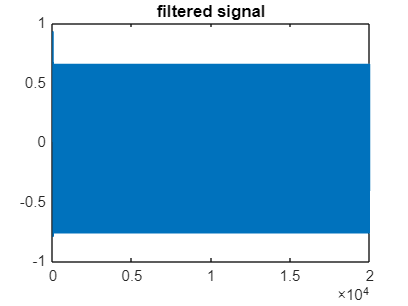

plot(filtered_signal)
title('filtered signal')

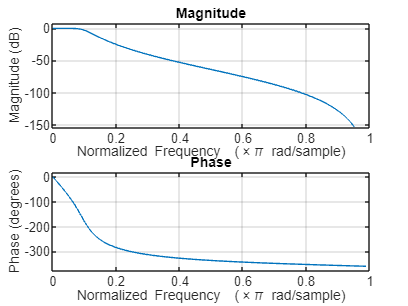

freqz(b, a);

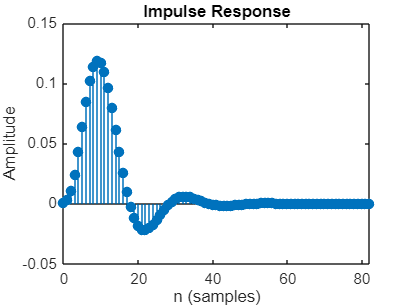

impz(b,a)

previous:

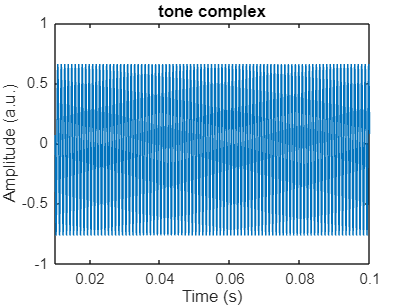


% Time limits for plotting
xmin = 0.01; % Lower time limit (s)
xmax = 0.1; % Upper time limit (s)
% Ensure that time vectors match the length of the filtered signals
t = linspace(0, length(filtered_signal)/fs, length(filtered_signal));

% Amplitude limits for plotting
ymin = -1; % Lower amplitude limit (a.u.)
ymax = 1; % Upper amplitude limit (a.u.)

% Plot the time signal for both
figure(1);
plot(t, filtered_signal);
title(type_signal);
xlabel('Time (s)');
ylabel('Amplitude (a.u.)');
xlim([xmin xmax]);

ylim([ymin ymax]);

Array indices must be positive integers or logical values.

ylim appears to be both a function and a variable. If this is unintentional, use 'clear ylim' to remove the variable 'ylim' from the workspace.


% Save the first figure immediately
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 15, 10]);
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [15, 10]);
set(gcf, 'PaperPosition', [0, 0, 15, 10]);
print(gcf, 'Figure1.pdf', '-dpdf', '-r300');

% Plotting specifications
ymin_mag = -20; % Lower magnitude limit (in dB)
ymax_mag = 20; % Upper magnitude limit (in dB)

% Plot Magnitude and Phase for Filter 1
figure(2);
subplot(2, 1, 1);
plot(f1, 20*log10(abs(H1))); % Magnitude in dB
title('Magnitude Response of Filter 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 fny1]);
ylim([ymin_mag ymax_mag]);

subplot(2, 1, 2);
plot(f1, angle(H1)); % Phase in radians
title('Phase Response of Filter 1');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
xlim([0 fny1]);

% Save the first figure immediately
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 15, 10]);
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [15, 10]);
set(gcf, 'PaperPosition', [0, 0, 15, 10]);
print(gcf, 'Figure2.pdf', '-dpdf', '-r300');

% Plot Real and Imaginary Parts for Filter 1
figure(4);
subplot(2, 1, 1);
plot(f1, real(H1)); % Real part of H1
title('Real Part of Filter 1 Response');
xlabel('Frequency (Hz)');
ylabel('Real Part');
xlim([0 fny1]);

subplot(2, 1, 2);
plot(f1, imag(H1)); % Imaginary part of H1
title('Imaginary Part of Filter 1 Response');
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');
xlim([0 fny1]);

% Plot Real and Imaginary Parts for Filter 2
figure(5);
subplot(2, 1, 1);
plot(f2, real(H2)); % Real part of H2
title('Real Part of Filter 2 Response');
xlabel('Frequency (Hz)');
ylabel('Real Part');
xlim([0 fny2]);

subplot(2, 1, 2);
plot(f2, imag(H2)); % Imaginary part of H2
title('Imaginary Part of Filter 2 Response');
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');
xlim([0 fny2]);

% Plot the pole-zero diagram for Filter 1
figure(6);
zplane(b1, a1); % b1 and a1 are the coefficients of the first filter
title('Pole-Zero Diagram of Filter 1');

% Plot the pole-zero diagram for Filter 2
figure(7);
zplane(d1, c1); % d1 and c1 are the coefficients of the second filter
title('Pole-Zero Diagram of Filter 2');

% Plot the Transfer Function Magnitude for Filter 1
figure(8);
plot(f1, abs(H1)); % Magnitude of H1
title('Transfer Function Magnitude of Filter 1');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
xlim([0 fny1]);

% Plot the Transfer Function Magnitude for Filter 2
figure(9);
plot(f2, abs(H2)); % Magnitude of H2
title('Transfer Function Magnitude of Filter 2');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
xlim([0 fny2]);

% Saving All Figures in PDF Format with 10x15 cm Size
% Loop through all figures and save with proper size settings
for i = 3:9
    figure(i);
    % Set the figure size in centimeters
    set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 15, 10]);
    % Set the paper size and position for saving
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperSize', [15, 10]);
    set(gcf, 'PaperPosition', [0, 0, 15, 10]);
    % Save the figure as a high-quality PDF
    print(gcf, sprintf('Figure%d.pdf', i), '-dpdf', '-r300');
end